clear; clc; close all;

function [X_Est, P_Est, GT] = myEKF(out)

%% Load Calibration %%
disp(['Calibration parameters generated by calibration_final.mlx.', ...
       newline, 'If file does not load please run calibration_final.mlx.'])
load('calib_params.mat');

%% Load dataset for trial in task
% Time vector
time = out.Sensor_ToF1.time;
N = length(time);

% Gyro data
gyro_raw = squeeze(out.Sensor_GYRO.signals.values);     % [3xM]
gyro_time = out.Sensor_GYRO.time;

% Accelerometer data
accel_raw = squeeze(out.Sensor_ACCEL.signals.values);   % [3xM]
accel_time = out.Sensor_ACCEL.time;

% ToF data
ToF1_raw = out.Sensor_ToF1.signals.values;
ToF2_raw = out.Sensor_ToF2.signals.values;
ToF3_raw = out.Sensor_ToF3.signals.values;

% Ground truth
GT_pos_raw = out.GT_position.signals.values;
GT_rot_raw = out.GT_rotation.signals.values;
GT_time = out.GT_position.time;

disp('Data setup complete.');

% EKF Parameters Setup
% Initial Ground Truth state
GT_pos0 = GT_pos_raw(1, 1:2)';
GT_q0 = GT_rot_raw(1, :);
GT_eul0 = quat2eul([GT_q0(1), GT_q0(2), GT_q0(3), GT_q0(4)], 'ZYX');
x0 = [GT_pos0; GT_eul0(1)];                     % Initial state vector x
P0 = diag([0.05^2, 0.05^2, deg2rad(2)^2]);      % Initial covariance P
Q0 = sqrt(tof_var);                             % Initial measurement noise Q

% Prediction parameters 
% [tof_bias, theta_offset, gyro_bias_z, accel_bias_fwd, w_pos, w_yaw_rate, w_accel, initial_velocity]
% Initial velocity set to 0 m/s because cart starts from stationary
w_pos = 0.5;    w_accel = 0.5; % Tunable Parameters based on model performance
predict_params = [tof_bias(1) tof_bias(2) tof_bias(3) theta_offset gyro_bias(1) accel_bias(2) w_pos sqrt(gyro_var(1)) w_accel 0.0];
curr = stepwise(x0, P0, predict_params, Q0);

% Collect states and estimations in arrays
X_Est = zeros(3, N);        X_Est(:, 1) = curr.x;
P_Est = zeros(3, 3, N);     P_Est(:, :, 1) = curr.P;
GT = zeros(3, N);           GT(:, 1) = x0;

disp('Initial process model setup complete.');

% Run EKF predict and update
disp('EKF Estimation start...')

for k = 1:(N-1)
    % Collect values for state prediction
    t_curr = time(k); t_next = time(k+1);
    dt = t_next - t_curr;

    % IMU data
    gyro_indices = find(gyro_time <= t_next);
    gyro_idx = gyro_indices(end);
    gyro_raw_vec = gyro_raw(:, gyro_idx);
    gyro_z_raw = gyro_raw_vec(1);

    accel_indices = find(accel_time <= t_next);
    accel_idx = accel_indices(end);
    accel_raw_vec = accel_raw(:, accel_idx);
    accel_fwd_raw = accel_raw_vec(2);

    % Use IMU data for state prediction
    predict(curr, gyro_z_raw, accel_fwd_raw, dt);

    % Collect values for measurement prediction
    % Magenetometer not used due to poor generalization to trial data
    % ToF data
    ToF_raw = [ToF1_raw(k+1); ToF2_raw(k+1); ToF3_raw(k+1)];

    % Use ToF data for state and covariance updates
    update(curr, ToF_raw);

    % Store estimated state and covariance
    X_Est(:, k+1) = curr.x;
    P_Est(:, :, k+1) = curr.P;

    % Store ground truth for later comparison with full estimation output X_Est
    [~, gt_idx] = min(abs(GT_time - t_next));
    GT_pos = GT_pos_raw(gt_idx, 1:2)';
    GT_quat = GT_rot_raw(gt_idx, :);
    GT_eul = quat2eul([GT_quat(1), GT_quat(2), GT_quat(3), GT_quat(4)], 'ZYX');
    GT_yaw = GT_eul(1); 
    GT(:, k+1) = [GT_pos; GT_yaw];
end
end

## Task Runner

Current setup runs Task 1. Comment out file with task1_5.mat and uncomment line after to run Task 2.

clear; clc; close all;

% LOAD TRIAL DATA
%file = 'trainingData/task1_5.mat';
file = 'trainingData/task2_2.mat';
data = load(file);

% FIND ESTIMATION
[X_Est, P_Est, GT_ekf] = myEKF(data.out);

Calibration parameters generated by calibration_final.mlx.
If file does not load please run calibration_final.mlx.
Data setup complete.
Initial process model setup complete.
EKF Estimation start...


disp('Estimation complete.')

Estimation complete.


## Use compareTrajectories

Evaluate estimation by finding compareTrajectories visualization

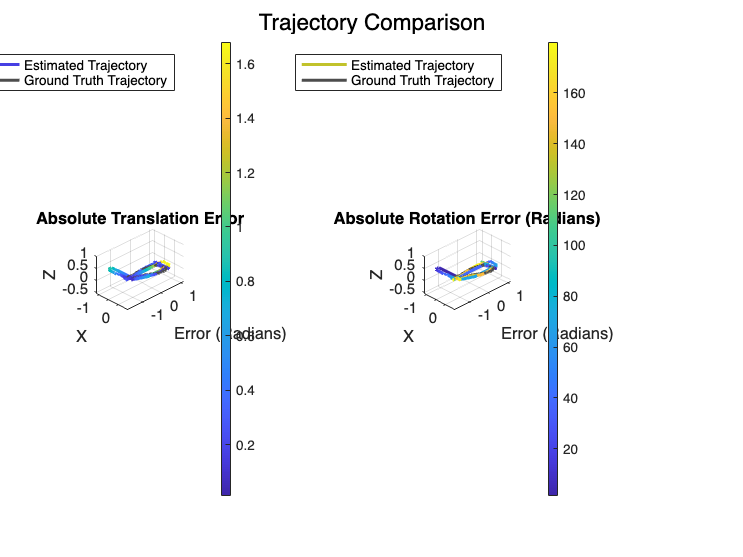

% Ground Truth
GT_pos   = data.out.GT_position.signals.values;  % [Nx3] (X,Y,Z)
GT_rot   = data.out.GT_rotation.signals.values;  % [Nx4] (W,X,Y,Z)
GT_time  = data.out.GT_position.time;            % [Nx1]
N = size(X_Est, 2);

GT_form(N) = rigidtform3d; % Preprocess to rigidform3d for valid format comparison
for i = 1:N
    qGT_raw = quaternion(GT_rot(i,1), GT_rot(i,2), GT_rot(i,3), GT_rot(i,4));
    RGT = rotmat(qGT_raw, 'frame');

    % Extract translation (use only X, Y, Z if available, assume Z=0 if only X,Y)
    if size(GT_pos, 2) >= 3
        tGT = GT_pos(i, 1:3); % Use X, Y, Z
    else
        tGT = [GT_pos(i, 1:2), 0]; % Use X, Y, assume Z=0
    end

    GT_form(i) = rigidtform3d(RGT, tGT); % RGT should be 3x3, tGT should be 1x3
end

estTforms(N) = rigidtform3d;

for i = 1:N
    % Estimated position (X, Y from EKF, assume Z=0)
    tEst = [X_Est(1, i), X_Est(2, i), 0]; % Create 1x3 row vector

    % Estimated orientation (Yaw from EKF)
    yaw_est = X_Est(3, i);
    cy = cos(yaw_est);
    sy = sin(yaw_est);

    % Create 3D rotation matrix from Yaw angle (rotation around Z-axis)
    REst = [ cy  -sy   0; ...
             sy   cy   0; ...
             0    0    1 ];

    % Create the rigid transform
    estTforms(i) = rigidtform3d(REst, tEst);
end
metrics = compareTrajectories(estTforms, GT_form);

% Compare trajectories
figure;
subplot(1, 2, 1)
plot(metrics, "absolute-translation");
title('Absolute Translation Error');
ylabel('Error (Radians)');
grid on;
view(45, 30);

subplot(1, 2, 2)
plot(metrics, "absolute-rotation");
title('Absolute Rotation Error (Radians)'); % Update title for clarity
ylabel('Error (Radians)');
grid on;
view(45, 30);
sgtitle('Trajectory Comparison');

## Evaluation Metrics

% Define time for plotting
% All array lengths are the same, can take GT or sensor time
N = length(GT_time);

% Extract yaw for comparison evaluation
yaw_GT = zeros(N, 1);
for i = 1:N
    qGT = quaternion(GT_rot(i,:));
    qGT = normalize(qGT);
    eulGT = eulerd(qGT, 'ZYX', 'frame');
    yaw_GT(i) = deg2rad(eulGT(1));
end
yaw_GT = unwrap(yaw_GT);
yaw_Est = unwrap(X_Est(3, :)');

% Convert to rigidForm format for compareTrajectories
GT_form(N) = rigidtform3d; estTforms(N) = rigidtform3d;
for i = 1:N
    RGT = rotmat(qGT, 'frame');
    tGT = GT_pos(i,1:min(3,end)); 
    tEst = [X_Est(1, i), X_Est(2, i), 0];
    yaw_est_i = yaw_Est(i);
    REst = [cos(yaw_est_i), -sin(yaw_est_i), 0; sin(yaw_est_i), cos(yaw_est_i), 0; 0, 0, 1];
    estTforms(i) = rigidtform3d(REst, tEst);
end

% Calculate RMSE between ground truth and estimation trajectories
error_x = X_Est(1,:)' - GT_pos(:,1);
error_y = X_Est(2,:)' - GT_pos(:,2);
rmse_position = sqrt(mean(error_x.^2 + error_y.^2));
disp(['Manual Position Absolute RMSE (m): ', num2str(rmse_position)]);

Manual Position Absolute RMSE (m): 0.2831



error_yaw = unwrap(yaw_Est - yaw_GT);
rmse_yaw_rad = sqrt(mean(error_yaw.^2));
rmse_yaw_deg = rad2deg(rmse_yaw_rad);
disp(['Manual Yaw Absolute RMSE (degrees): ', num2str(rmse_yaw_deg)]);

Manual Yaw Absolute RMSE (degrees): 4.5926


## Generate plots

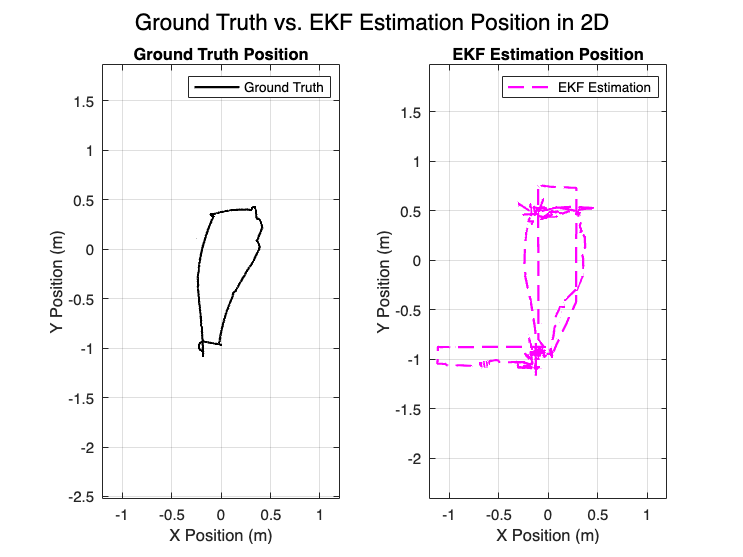

% Trajectory comparison in 2D
figure;
subplot(1, 2, 1); 
plot(GT_pos(:,1), GT_pos(:,2), 'black-', 'LineWidth', 1.5);
title('Ground Truth Position');
xlabel('X Position (m)');
ylabel('Y Position (m)');
xlim([-1.2 1.2]);
ylim([-1.2 1.2]); 
axis equal; grid on;
legend('Ground Truth')

subplot(1, 2, 2);
plot(X_Est(1,:), X_Est(2,:), 'magenta--', 'LineWidth', 1.5);
title('EKF Estimated Position');
xlabel('X Position (m)');
ylabel('Y Position (m)');
xlim([-1.2 1.2]);
ylim([-1.2 1.2]); 
axis equal; grid on;
title('EKF Estimation Position');
legend('EKF Estimation')
sgtitle('Ground Truth vs. EKF Estimation Position in 2D')

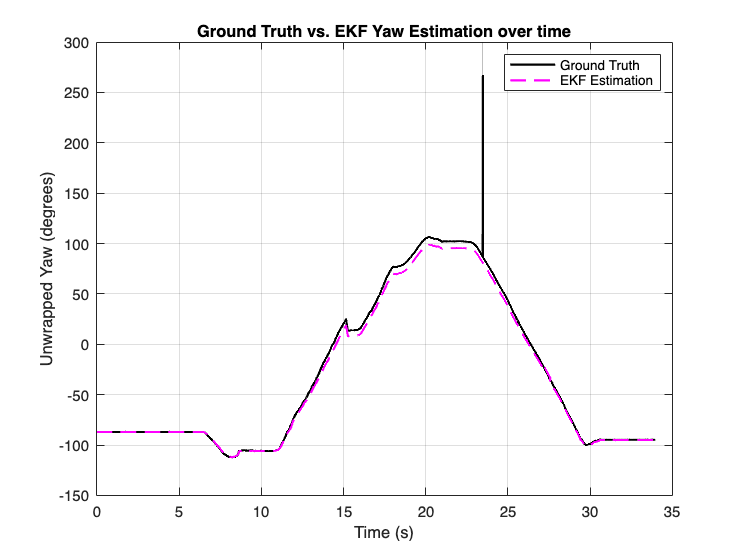



% Compare yaw between ground truth and estimated
unwrapped_yaw_GT = rad2deg(unwrap(yaw_GT));
unwrapped_yaw_Est = rad2deg(unwrap(yaw_Est));

figure;
plot(GT_time, unwrapped_yaw_GT, 'black-', 'LineWidth', 1.5);
hold on;
plot(GT_time, unwrapped_yaw_Est, 'magenta--', 'LineWidth', 1.5);
hold off;
xlabel('Time (s)')
ylabel('Unwrapped Yaw (degrees)')
legend('Ground Truth', 'EKF Estimation')
title('Ground Truth vs. EKF Yaw Estimation over time')
grid on;


% Yaw Error over time
figure;
yaw_error_deg = rad2deg(unwrap(yaw_Est - yaw_GT));
plot(GT_time, yaw_error_deg, 'k-', 'LineWidth', 1); 
xlabel('Time (s)');
ylabel('Yaw Error (degrees)');
ylabel('Unwrapped Yaw (degrees)');
title('Ground Truth vs. EKF Yaw Error over time');
legend('Ground Truth Yaw', 'EKF Estimated Yaw');

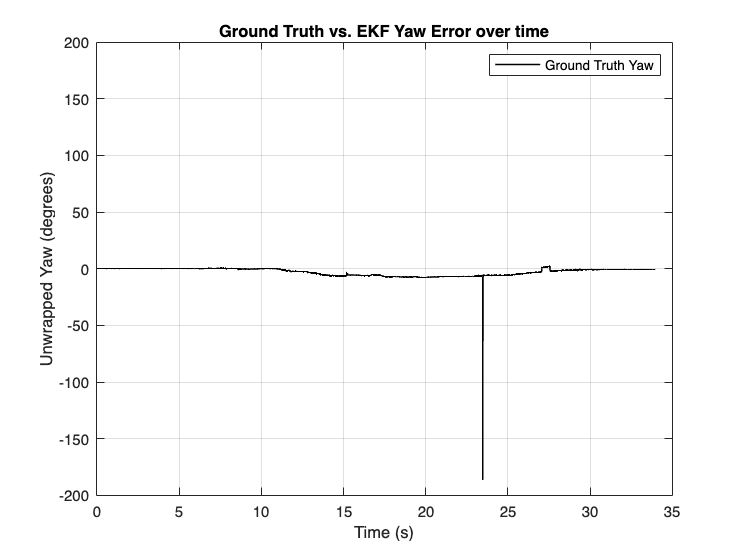

ylim([-200 200])
grid on;

## EKF Functions

#### Prediction

function predict(obj, gyro_raw, accel_raw, dt)
    % Predicts state using gyro for yaw rate and accelerometer for velocity estimation.

    % Collect data
    % State vector [x, y, yaw]
    x_prev = obj.x;
    P_prev = obj.P;
    yaw_prev = x_prev(3);

    % Use calibrated gyroscope and accelerometer readings for state prediction
    gyro_cal = gyro_raw - obj.gyro_bias;        % Calibrate gyro
    accel_cal = accel_raw - obj.accel_bias;     % Calibrate accelerometer

    % Accelerometer used to predict velocity
    % Gyroscope used to predict yaw
    % Velocity state update: v = v0 + a∆t
    obj.v_est = obj.v_est + accel_cal * dt;

    % State Transition Model f(x, u)
    % Predict next state based on previous state, corrected inputs, and estimated velocity
    x_k = zeros(3,1);
    x_k(1) = x_prev(1) + obj.v_est * cos(yaw_prev) * dt;
    x_k(2) = x_prev(2) + obj.v_est * sin(yaw_prev) * dt;
    x_k(3) = yaw_prev + gyro_cal * dt;
    x_k(3) = wrapToPi(x_k(3)); % Normalize predicted angle

    % State Transition Jacobian F
    F = [   1  0  -obj.v_est * sin(yaw_prev) * dt;
            0  1   obj.v_est * cos(yaw_prev) * dt;
            0  0   1 ];

    % Process noise Q_k
    % Corresponds to state vector [x, y, yaw]
    % pos = initial_pos + v*dt + 1/2*a*dt^2 >> process noise added to xy
    % yaw = initial_yaw + omega*dt

    Q_accel = 0.5*obj.w_accel*dt^2;             % 1/2*a*dt^2
    Q_gyro = obj.w_yaw_rate*dt;                 % omega*dt

    Q_k = diag([(obj.w_pos * dt) + Q_accel, ... % x
                (obj.w_pos * dt) + Q_accel, ... % y
                Q_gyro]);                       % yaw

     % Compute Covariance
     obj.P = F * P_prev * F' + Q_k;
     obj.P = 0.5 * (obj.P + obj.P');
     obj.x = x_k; % State update
end

#### Update

function update(obj, z)
    % ToF only used to update position since it's a distance sensor
    z = double(z(:));
    h_x = measurement_model(obj, obj.x);
    H = numericalJacobian(obj, obj.x); % Calculate full Jacobian
    H_pos = H;
    H_pos(:, 3) = 0; 

    % Calculate measurement covariance and Kalman gain
    S = H_pos * obj.P * H_pos' + obj.R;
    K = obj.P * H_pos' / S;

    y = z - h_x;

    % Update state and covariance
    obj.x = obj.x + K * y;
    obj.x(3) = wrapToPi(obj.x(3));

    I = eye(size(obj.P,1));
    obj.P = (I - K * H_pos) * obj.P * (I - K * H_pos)' + K * obj.R * K';
end

### Helper Functions

function h = measurement_model(obj, state)
    h = zeros(3, 1);
    for i = 1:3
        % Find measurement prediction
        h(i) = useToF(obj, state, i);
    end
end

function dist = useToF(obj, state, sensor_index)
    % Calculates the expected distance for a single ToF sensor using ray casting.
    x_r = state(1);
    y_r = state(2);
    yaw_r = state(3); % Already normalized in predict/update

    % Calibrates ToF with offsets
    rel_pos_sensor = obj.tof_bias(:, sensor_index);
    rel_angle_sensor = obj.tof_rel_angle(sensor_index);

    % Calculate sensor's global position
    c_yaw = cos(yaw_r);
    s_yaw = sin(yaw_r);
    rot_matrix = [c_yaw, -s_yaw; s_yaw, c_yaw];
    sensor_offset_world = rot_matrix * rel_pos_sensor;
    sx = x_r + sensor_offset_world(1);
    sy = y_r + sensor_offset_world(2);

    % Calculate sensor's global orientation (angle)
    sensor_yaw = wrapToPi(yaw_r + rel_angle_sensor);
    c_s_yaw = cos(sensor_yaw);
    s_s_yaw = sin(sensor_yaw);

    % Initialize list of distances
    distances = [];

    % Check intersection with each wall using the helper function
    distances = [distances, castWallDistance(obj, sx, sy, c_s_yaw, s_s_yaw, obj.arena_dim.x_max, 'x', 1)];
    distances = [distances, castWallDistance(obj, sx, sy, c_s_yaw, s_s_yaw, obj.arena_dim.x_min, 'x', 1)];
    distances = [distances, castWallDistance(obj, sx, sy, c_s_yaw, s_s_yaw, obj.arena_dim.y_max, 'y', 1)];
    distances = [distances, castWallDistance(obj, sx, sy, c_s_yaw, s_s_yaw, obj.arena_dim.y_min, 'y', 1)];

    % Filter out invalid entries (NaN)
    distances = distances(~isnan(distances));
    
    % Return the minimum valid distance
    if isempty(distances)
        dist = 10.0; % Return a large distance
    else
        dist = min(distances);
    end
end

function d = castWallDistance(obj, sx, sy, c_s_yaw, s_s_yaw, wall_coord, axis, forward)
    d = NaN;  % Default to invalid

    if axis == 'x'
        if abs(c_s_yaw) > obj.epsilon
            d_try = (wall_coord - sx) / c_s_yaw;
            py = sy + d_try * s_s_yaw;
            if d_try > obj.epsilon && py >= obj.arena_dim.y_min && py <= obj.arena_dim.y_max
                d = d_try;
            end
        end
    elseif axis == 'y'
        if abs(s_s_yaw) > obj.epsilon
            d_try = (wall_coord - sy) / s_s_yaw;
            px = sx + d_try * c_s_yaw;
            if d_try > obj.epsilon && px >= obj.arena_dim.x_min && px <= obj.arena_dim.x_max
                d = d_try;
            end
        end
    end
end


function H = numericalJacobian(obj, state)
    delta = 1e-7;
    H = zeros(3, 3);
    for j = 1:3
        x_plus = state; x_minus = state;
        x_plus(j) = x_plus(j) + delta;
        x_minus(j) = x_minus(j) - delta;
        if j == 3
            x_plus(3) = wrapToPi(x_plus(3));
            x_minus(3) = wrapToPi(x_minus(3));
        end
        h_plus = measurement_model(obj, x_plus);
        h_minus = measurement_model(obj, x_minus);
        derivative = (h_plus - h_minus) / (2 * delta);
        H(:, j) = derivative;
    end
end
